% Read the image
grayImage = A_doub

grayImage = 4032×3024 uint8 matrix
    0    0    0    0    0    0    0    0    0    0   26   26    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0   26   26    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0   13   26    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0   13   26    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  

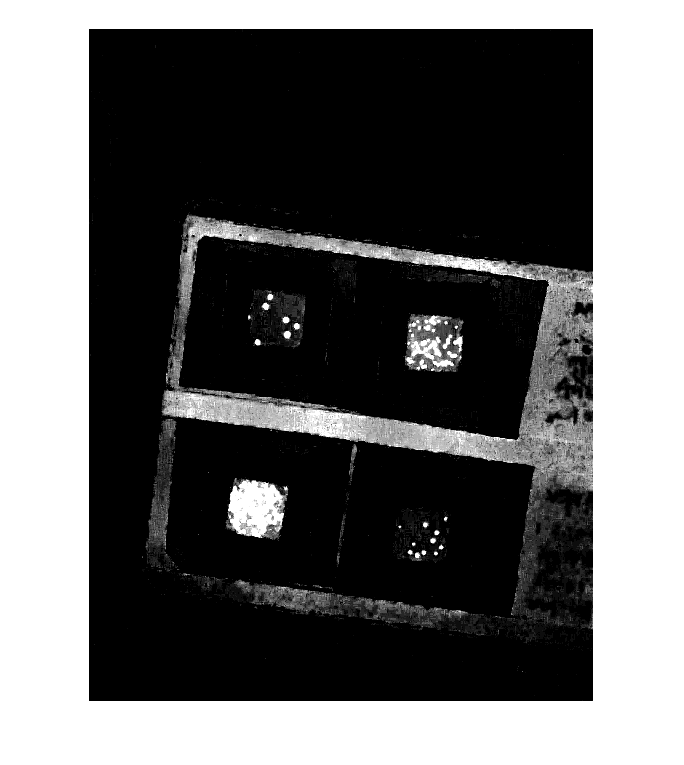

% Display the image.
imshow(grayImage);

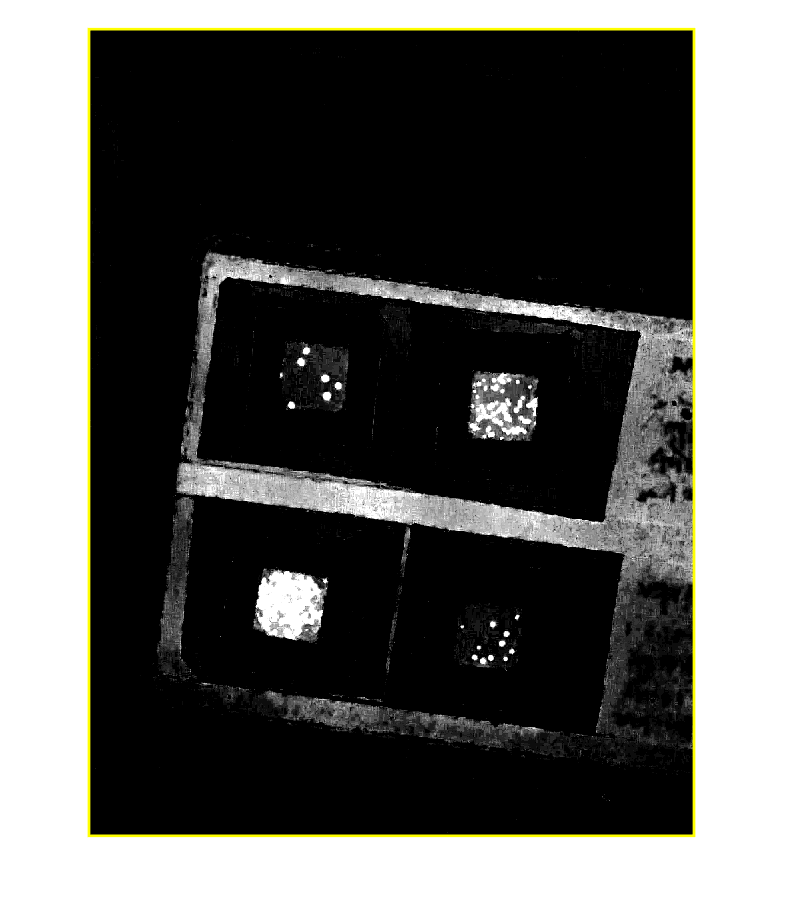

S = regionprops(grayImage,'BoundingBox','Area');
[MaxArea,MaxIndex] = max(vertcat(S.Area));
imshow(grayImage,'InitialMagnification',20)
%// Highlight the required object
hold on
rectangle('Position',S(MaxIndex).BoundingBox,'LineWidth',2,'EdgeColor','y')

Length = S(MaxIndex).BoundingBox(3);
Height = S(MaxIndex).BoundingBox(4);
maxBrightness = max(grayImage(:))

maxBrightness = uint8
255


% Cropping the image
% Get all rows and columns where the image is nonzero
[nonZeroRows,nonZeroColumns] = find(grayImage);
% Get the cropping parameters
topRow = min(nonZeroRows(:));
bottomRow = max(nonZeroRows(:));
leftColumn = min(nonZeroColumns(:));
rightColumn = max(nonZeroColumns(:));
% Extract a cropped image from the original.
croppedImage = grayImage(topRow:bottomRow, leftColumn:rightColumn);
% Display the original gray scale image.
figure
imshow(croppedImage, []);